# Advent of Code

## `--- Day 6: Universal Orbit Map ---`

`Part 1`

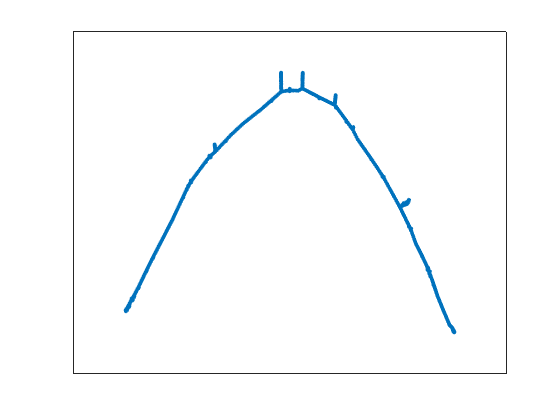

clear;clc;
fileID=fopen('daysix.txt');
inp=textscan(fileID,'%s'); inp=inp{1,1};
C={};
for i=1:1:length(inp)
    temp=inp{i,1};
    C{i,1}=temp(1:3); C{i,2}=temp(5:7);
end
G=graph(C{1,1},C{1,2});
for j=2:1:length(inp)
    G=addedge(G,C{j,1},C{j,2});
end
plot(G)

e=G.Nodes; e=table2cell(e);
an=[]; con=1;
for k=1:1:length(e)
    an(1,con)=length(shortestpath(G,'COM',e{k,1}))-1;
    con=con+1;  
end
disp(sum(an))

      261306



Part 2:

anf=length(shortestpath(G,'YOU','SAN'))-3;
disp(anf)

   382

